% Parameters
alpha  = 1 + mod(273,3)

alpha = 1

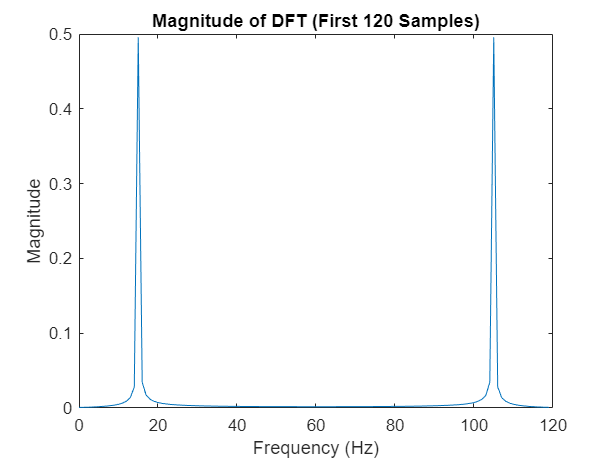

duration = 2;  % seconds
sampling_rate = 120;  % samples per second
frequency = 15 * alpha;  % α Hz
N = duration * sampling_rate;  % Total number of samples

% Generate the time vector
t = linspace(0, duration, N);

% Generate the unit amplitude sinusoidal signal
signal = sin(2 * pi * frequency * t);

% Calculate the Discrete Fourier Transform (DFT) of the first 120 samples
dft_120 = abs(fft(signal(1:120))/120);

% Calculate the Discrete Fourier Transform (DFT) of the first 130 samples
dft_130 = abs(fft(signal(1:130))/130);
% Frequency axis for plotting
freq_axis = 0:119;
freq_axis1 =(0:129)*120/130;

% Plot the magnitude of the DFT for the first 120 samples

plot(freq_axis, dft_120);
title('Magnitude of DFT (First 120 Samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

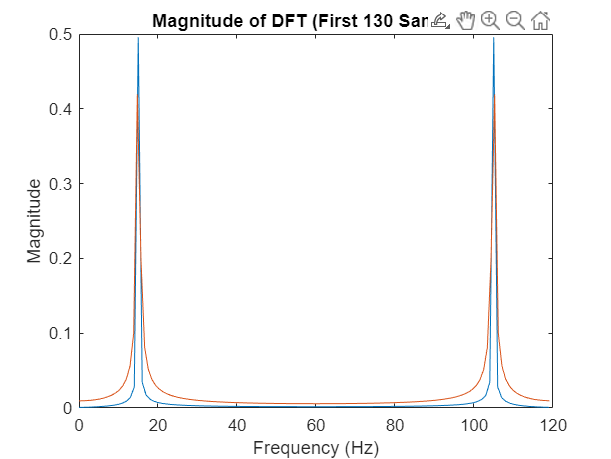


% Plot the magnitude of the DFT for the first 130 samples
plot(freq_axis, dft_120);
title('Magnitude of DFT (First 120 Samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
hold on
plot(freq_axis1, dft_130);
title('Magnitude of DFT (First 130 Samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
hold off

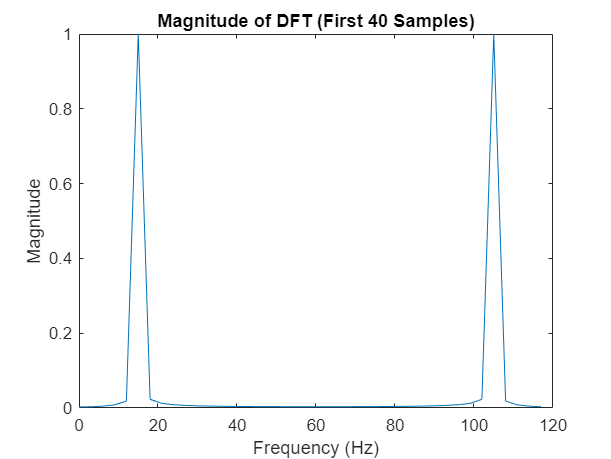


% Show the plots
figure;

dft_40 = abs(fft(signal(1:40))/max(fft(signal(1:40))));
freq_axis2 =(0:39)*120/40;
plot(freq_axis2, dft_40);
title('Magnitude of DFT (First 40 Samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

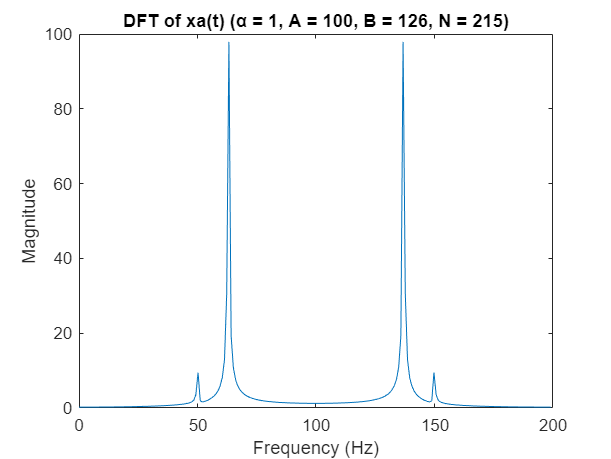

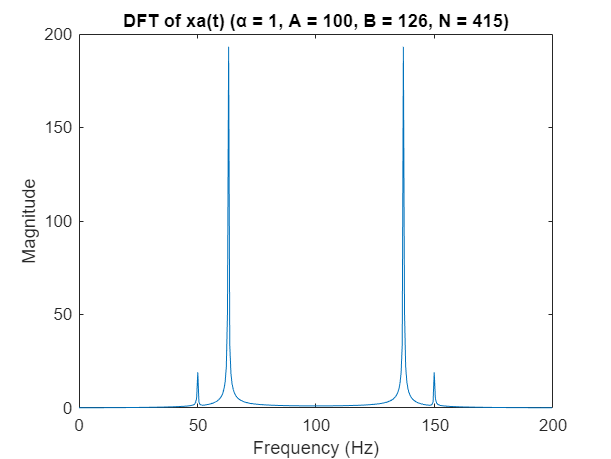

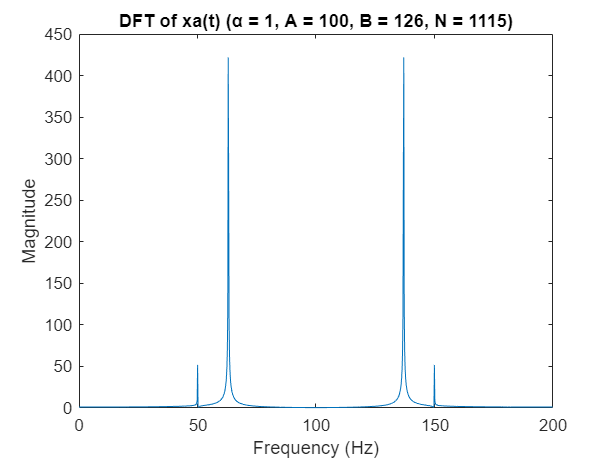

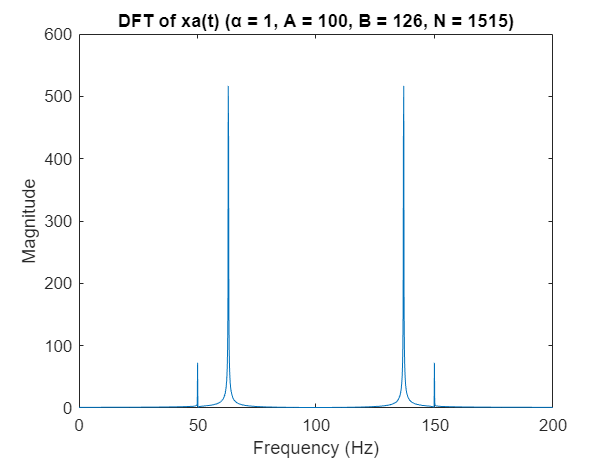

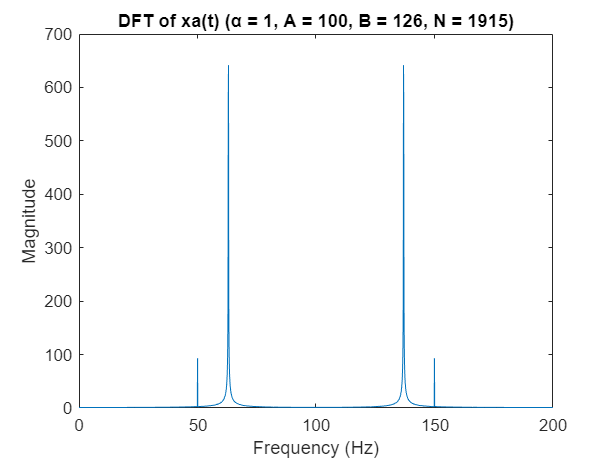

% Parameters
%alpha_values =  1;
A_values = 100;
B_values = 126;
duration = 10;  % seconds

% Generate time vector
t = linspace(0, duration, duration * 200);
    
    % Generate the signal xa(t)
signal = 0.1 * sin(A_values * pi * t) + cos(B_values * pi * t);

    % Plot the DFT of the signal for different sample counts
sample_counts = [215, 415, 1115, 1515, 1915];    
for j = 1:length(sample_counts)    
    N = sample_counts(j);
    sample_signal = signal(1:N);   
        
        % Compute the DFT and the frequency axis
    dft = fft(sample_signal);
    freq_axis = (0:N-1)*200/N;   

        % Plot the DFT
    figure;   
    plot(freq_axis, abs(dft));   
    title(sprintf('DFT of xa(t) (α = %d, A = %d, B = %d, N = %d)', alpha, A_values, B_values, N));   
    xlabel('Frequency (Hz)');   
    ylabel('Magnitude');   
end       

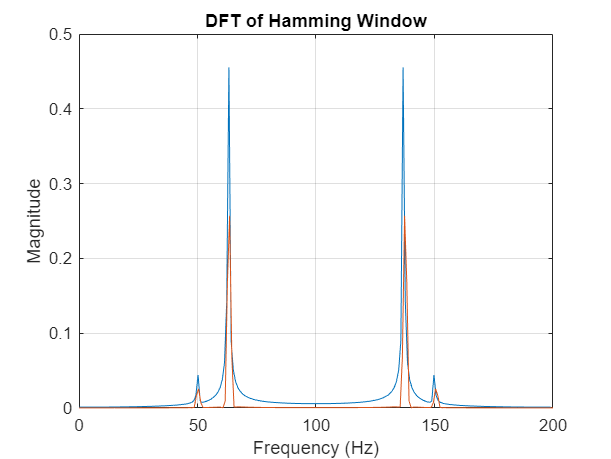

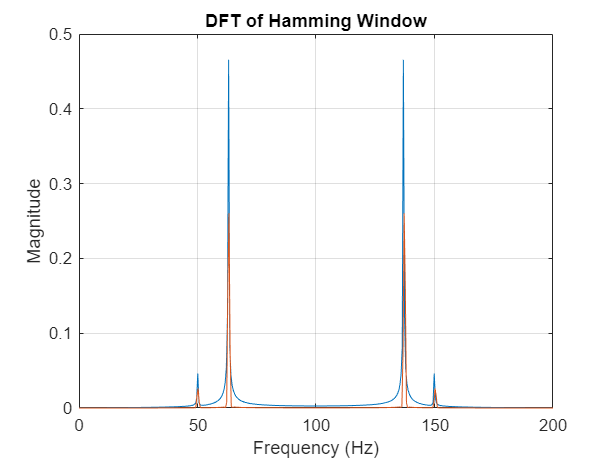

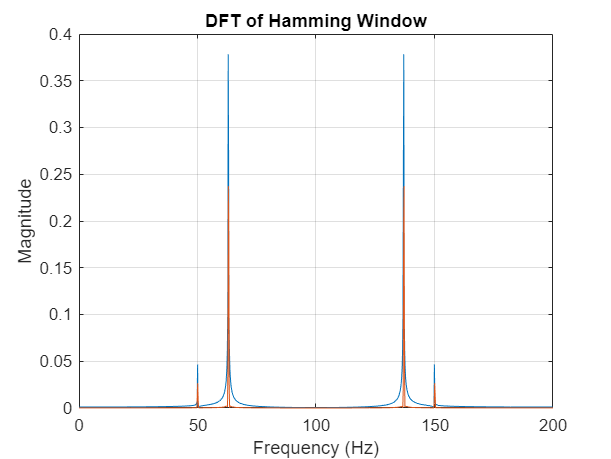

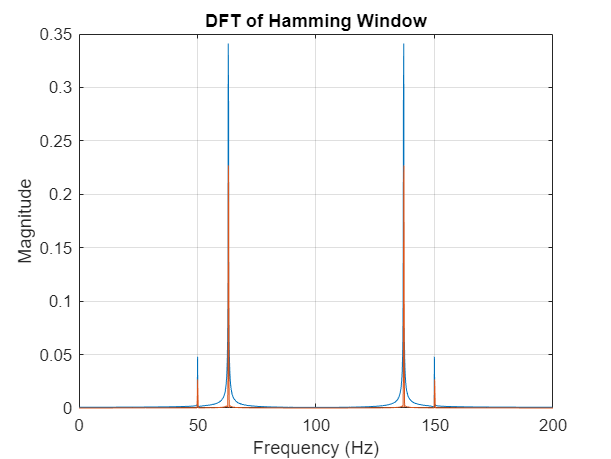

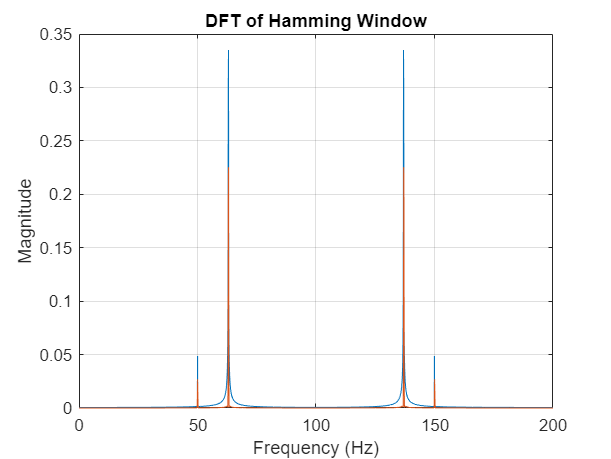


sample_counts = [215, 415, 1115, 1515, 1915];    
for j = 1:length(sample_counts)    
    N = sample_counts(j);
    sample_signal = signal(1:N);   
    dft = abs(fft(sample_signal)/N);
    freq_axis = (0:N-1)*200/N;   
    window = hamming(N);
    windowed_signal = signal(1:N) .* window';
    dft_windowed = abs(fft(windowed_signal))/N;
    freq_axis_windowed = linspace(0, 200, N);
    figure; 
    plot(freq_axis, dft);
    grid on;
    xlabel('Frequency (Hz)');   
    ylabel('Magnitude');
    hold on
    plot(freq_axis_windowed, dft_windowed);    
    title(sprintf('DFT of Hamming Window'));
    xlabel('Frequency (Hz)');    
    ylabel('Magnitude') 
    hold off
end    

% Load the data from the file
data = load('Exp4Data1.txt');
fs = 5000; % Assume a sampling frequency of 5000 Hz (adjust if necessary)
N = length(data);

wind = hamming(500);
windowed_signal1 = data .* wind';

% Perform FFT with zero-padding to improve frequency resolution
N_fft = 10000; % Number of points for FFT (zero-padding)
fft_result = abs(fft(windowed_signal1, N_fft))/N_fft;

% Frequency axis in terms of Fs
freq_axis = (0:N_fft-1) / N_fft * fs;

% Plot the magnitude of the FFT result
figure;
subplot(2, 1, 1);
plot(freq_axis, fft_result);
title('Magnitude of FFT (Hamming Window)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Find the frequencies of the two components (peaks)
[~, indices] = findpeaks(abs(fft_result), 'SortStr', 'descend', 'NPeaks', 2);
frequencies_hamming = freq_axis(indices);

fprintf('Frequency components using Hamming window:\n');

Frequency components using Hamming window:


fprintf('Frequency 1: %.3f Hz\n', frequencies_hamming(1));

Frequency 1: 1140.500 Hz


fprintf('Frequency 2: %.3f Hz\n', frequencies_hamming(2));

Frequency 2: 3859.500 Hz


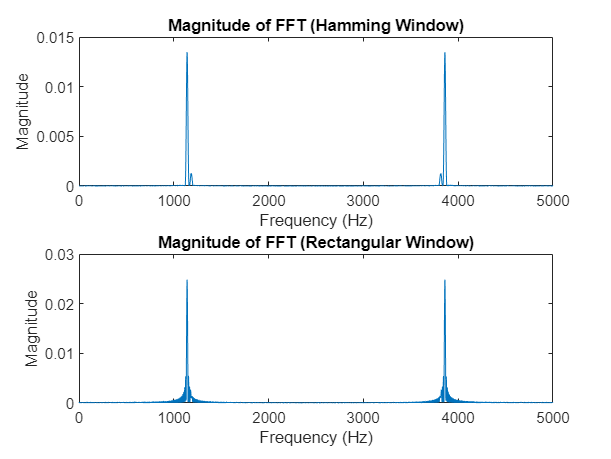


% Repeat the analysis using a rectangular window
rectangular_window = rectwin(N);
data_rectangular = data .* rectangular_window';

% Perform FFT with zero-padding on the rectangular windowed signal
fft_result_rectangular = abs(fft(data_rectangular, N_fft))/N_fft;

% Plot the magnitude of the FFT result for rectangular window
subplot(2, 1, 2);
plot(freq_axis, abs(fft_result_rectangular));
title('Magnitude of FFT (Rectangular Window)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


% Find the frequencies of the two components (peaks) for rectangular window
[~, indices_rectangular] = findpeaks(fft_result_rectangular, 'SortStr', 'descend', 'NPeaks', 2);
frequencies_rectangular = freq_axis(indices_rectangular);

fprintf('Frequency components using Rectangular window:\n');

Frequency components using Rectangular window:


fprintf('Frequency 1: %.3f Hz\n', frequencies_rectangular(1));

Frequency 1: 1140.500 Hz


fprintf('Frequency 2: %.3f Hz\n', frequencies_rectangular(2));

Frequency 2: 3859.500 Hz
